%test code for polarization follow up
%addpath("*\GitHub\femto_matlab\examples")
%addpath("*\GitHub\femto_matlab\Utilities")

objCylinder = CylindricalHelix(0,0,0,0.2,0,0,5,0.05,0.02,0.050)

objCylinder =   CylindricalHelix with properties:

               diameter: 0.0500
                   step: 0.0200
                  pitch: 0.0500
                   name: 'Constant circular helix'
                   vpos: 2
                   vcut: 5
                      n: 1.4600
                 startX: 0
                  stopX: 0.2000
                 startY: 0
                  stopY: 0
                 startZ: 0
                  stopZ: 0
                 Length: []
           Writing_Time: []
                 hGraph: [1×1 GraphicsPlaceholder]
                version: 'v.'
               selected: []
         long_wait_time: 0.1000
        short_wait_time: 0.0100
                    tag: []
        GCODE_wait_mode: "auto"
    advanced_GCODE_mode: 0


[~,X_GCODE,Y_GCODE,Z_GCODE,v_GCODE,Shutter_GCODE]=objCylinder.GCODE_write()

X_GCODE =          0    0.0061    0.0121    0.0182    0.0243    0.0303    0.0364    0.0425    0.0485    0.0546    0.0607    0.0667    0.0728    0.0789    0.0849    0.0910    0.0971    0.1031    0.1092    0.1153    0.1213    0.1274    0.1335    0.1395    0.1456    0.1517    0.1577    0.1638    0.1699    0.1759    0.1820    0.1881    0.1941


Y_GCODE =          0    0.0173    0.0250    0.0189    0.0023   -0.0155   -0.0248   -0.0203   -0.0046    0.0137    0.0243    0.0216    0.0068   -0.0117   -0.0237   -0.0226   -0.0090    0.0096    0.0229    0.0235    0.0111   -0.0074   -0.0218   -0.0242   -0.0132    0.0052    0.0206    0.0247    0.0151   -0.0029   -0.0192   -0.0249   -0.0168


Z_GCODE =     0.0250    0.0181    0.0012   -0.0164   -0.0249   -0.0196   -0.0035    0.0146    0.0246    0.0209    0.0057   -0.0127   -0.0240   -0.0221   -0.0079    0.0106    0.0233    0.0231    0.0101   -0.0085   -0.0224   -0.0239   -0.0122    0.0063    0.0213    0.0245    0.0141   -0.0040   -0.0200   -0.0248   -0.0160    0.0017    0.0185


v_GCODE =      2     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5


Shutter_GCODE =      0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



GCODE_array=[X_GCODE' Y_GCODE' Z_GCODE' v_GCODE' Shutter_GCODE' zeros(size(X_GCODE')) zeros(size(X_GCODE')) zeros(size(X_GCODE'))]

GCODE_array =          0         0    0.0250    2.0000         0         0         0         0
    0.0061    0.0173    0.0181    5.0000    1.0000         0         0         0
    0.0121    0.0250    0.0012    5.0000    1.0000         0         0         0
    0.0182    0.0189   -0.0164    5.0000    1.0000         0         0         0
    0.0243    0.0023   -0.0249    5.0000    1.0000         0         0         0
    0.0303   -0.0155   -0.0196    5.0000    1.0000         0         0         0
    0.0364   -0.0248   -0.0035    5.0000    1.0000         0         0         0
    0.0425   -0.0203    0.0146    5.0000    1.0000         0         0         0
    0.0485   -0.0046    0.0246    5.0000    1.0000         0         0         0
    0.0546    0.0137    0.0209    5.0000    1.0000         0         0         0


GCODE_p_array=GCODE_array_add_polarization(GCODE_array)

shifts_array =     0.0061    0.0173
    0.0061    0.0077
    0.0061   -0.0061
    0.0061   -0.0166
    0.0061   -0.0178
    0.0061   -0.0092
    0.0061    0.0045
    0.0061    0.0157
    0.0061    0.0182
    0.0061    0.0107


beta =     1.2329
    0.9041
   -0.7894
   -1.2195
   -1.2428
   -0.9897
    0.6349
    1.2021
    1.2498
    1.0545


theta =     2.8037
    2.4749
    0.7814
    0.3513
    0.3280
    0.5811
    2.2057
    2.7729
    2.8205
    2.6253


theta =     2.8037
    2.4749
    0.7814
    0.3513
    0.3280
    0.5811
    2.2057
    2.7729
    2.8205
    2.6253


GCODE_p_array =          0         0    0.0250    2.0000         0         0         0         0    1.4019
    0.0061    0.0173    0.0181    5.0000    1.0000         0         0         0    1.2374
    0.0121    0.0250    0.0012    5.0000    1.0000         0         0         0    0.3907
    0.0182    0.0189   -0.0164    5.0000    1.0000         0         0         0    0.1756
    0.0243    0.0023   -0.0249    5.0000    1.0000         0         0         0    0.1640
    0.0303   -0.0155   -0.0196    5.0000    1.0000         0         0         0    0.2906
    0.0364   -0.0248   -0.0035    5.0000    1.0000         0         0         0    1.1029
    0.0425   -0.0203    0.0146    5.0000    1.0000         0         0         0    1.3864
    0.0485   -0.0046    0.0246    5.0000    1.0000         0         0         0    1.4103
    0.0546    0.0137    0.0209    5.0000    1.0000         0         0         0    1.3126


GCODE_p_array =          0         0    0.0250    2.0000         0         0         0         0    1.4019
    0.0061    0.0173    0.0181    5.0000    1.0000         0         0         0    1.2374
    0.0121    0.0250    0.0012    5.0000    1.0000         0         0         0    0.3907
    0.0182    0.0189   -0.0164    5.0000    1.0000         0         0         0    0.1756
    0.0243    0.0023   -0.0249    5.0000    1.0000         0         0         0    0.1640
    0.0303   -0.0155   -0.0196    5.0000    1.0000         0         0         0    0.2906
    0.0364   -0.0248   -0.0035    5.0000    1.0000         0         0         0    1.1029
    0.0425   -0.0203    0.0146    5.0000    1.0000         0         0         0    1.3864
    0.0485   -0.0046    0.0246    5.0000    1.0000         0         0         0    1.4103
    0.0546    0.0137    0.0209    5.0000    1.0000         0         0         0    1.3126


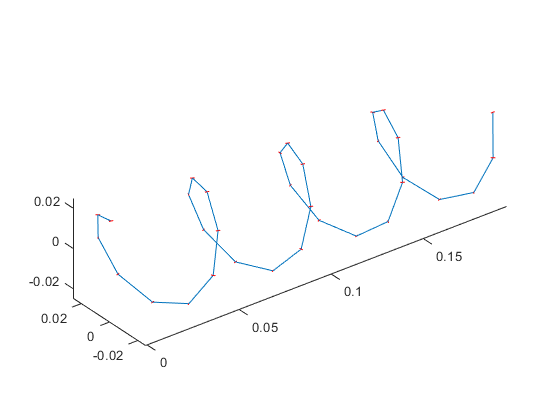

figure
plot3(GCODE_array(:,1),GCODE_array(:,2), GCODE_array(:,3))
hold on
for ii=1:size(GCODE_p_array,1)
    x=GCODE_p_array(ii,1);
    y=GCODE_p_array(ii,2);
    angle=(GCODE_p_array(ii,9)*2)*pi/180; %conversion in radiants
    dx=0.002*cos(angle);
    dy=0.002*sin(angle);
    plot3([x-dx/2 x+dx/2],[y-dy/2 y+dy/2],[GCODE_p_array(ii,3) GCODE_p_array(ii,3)], 'r')  
end
axis equal


file_name='test_linear_A.pgm';
incipit='test for linear A GCODE';
n=1.45;
setup='Ant';
mode='incremental';

%[CompiledFileName]=GCODE_Compile_V5(file_name,n,mode,setup,GCODE_p_array,incipit)